# Blackjack Simulation

## Creating Decks

% card values
% number cards = number
% face cards = 10
% ace card = 1 or 11 depending on situation


% Game will use 6 x 52-card decks
% 13 cards in every suite (x4)
% Total of 312 cards when combined



## Pre-allocating space & Pre-defined parameters

% Playing 100 hands of blackjack
% Cards are drawn without replacement
numOfGames = 10;
winsA = zeros(numOfGames,1);
winsB = zeros(numOfGames,1);


## Simulating

for i= 1:numOfGames
%     winsA(i) = mean(playA(100));
    winsB(i) = mean(playB(100));
end

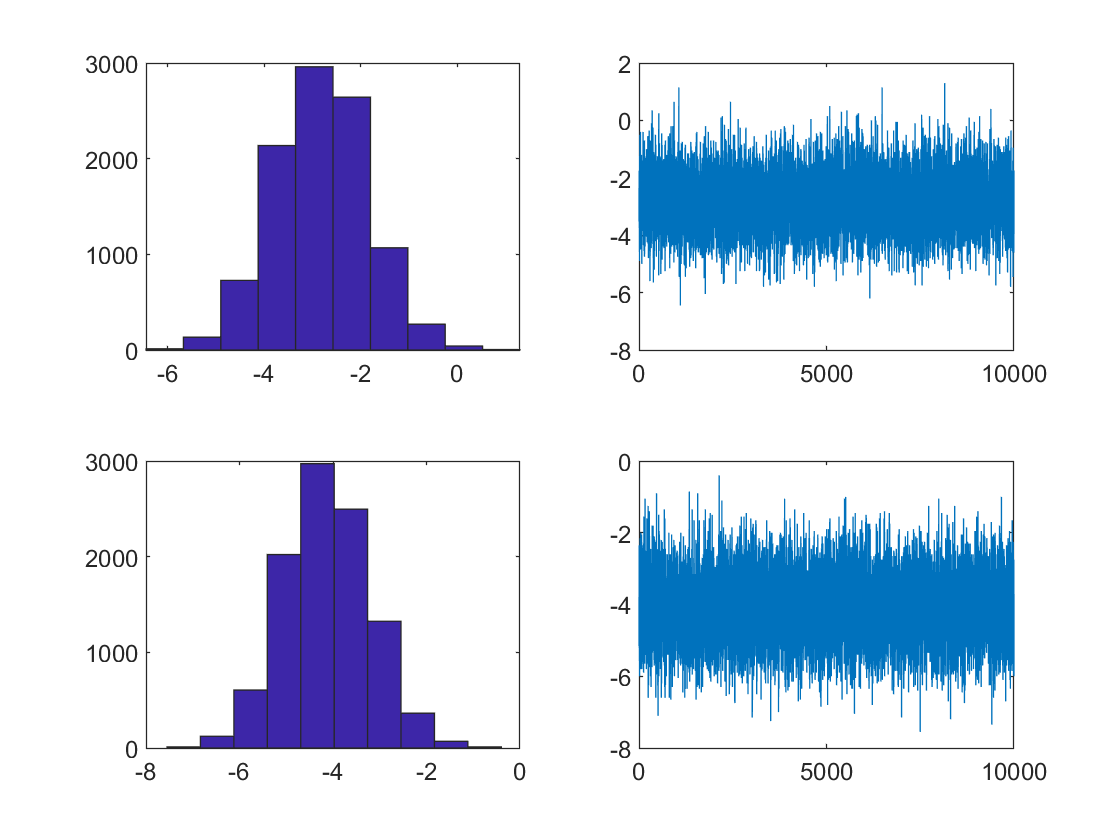


subplot(2,2,1)
hist(winsA)
subplot(2,2,2)
plot(winsA)
subplot(2,2,3)
hist(winsB)
subplot(2,2,4)
plot(winsB)

function [cardsInHand, deck] = below16(hand,deck)
    if sum(hand) < 16
        [card, deck] = hit(deck);
        if card == 11 & sum(hand)+11 > 21
            card = 1;
        end
        % Adding new card to hand
        cardsInHand = [card,hand];
        
        [cardsInHand,deck] = below16(cardsInHand,deck);
    else
        cardsInHand = hand;
        deck = deck;
    end
end

function [win] = compare(myhand,dealerhand)
    if sum(myhand) > sum(dealerhand)
        win = 10;
    elseif sum(myhand) < sum(dealerhand)
        win = -10;
    elseif sum(myhand) == sum(dealerhand)
        win = 0;
    end
end

% If endOfGame is true and the deck is less than 20, then it will reset the deck
function deck = shuffle(deck)
    values = [2 3 4 5 6 7 8 9 10 10 10 10 11];
    decks = values.*ones(4,13,6);
    comboDeck = reshape(decks,[1,312]);
    deck = randsample(comboDeck,312,false);
end
% Hitting
function [card, deck] = hit(deck,varargin)
% If the deck is empty, then the deck will initialized (start of game)
    if nargin == 2
        status = varargin{1};
    else
        status = -1;
    end
    if length(deck) == 0
        values = [2 3 4 5 6 7 8 9 10 10 10 10 11];
        decks = values.*ones(4,13,6);
        comboDeck = reshape(decks,[1,312]);
        deck = randsample(comboDeck,312,false);
        card = deck(1:4);
        deck(1:4) = [];
    elseif status == true
        card = deck(1:4);
        deck(1:4) = [];
% Otherwise, pull out a card from the deck
    else
        card = deck(1);
        deck(1) = [];
    end
end

% Strategy A
function [win,deck] = strategyA(deck)
    % Start of game
    startOfGame = true;
   [cards, deck] = hit(deck,startOfGame);
    
    % Both dealer and player get 2 cards to begin with
    playerHand = cards(1:2);
    dealerHand = cards(3:4);
  
    % Player will hit til 16
    [playerHand, deck] = below16(playerHand,deck);
    
    if sum(playerHand) <= 21
          if sum(playerHand) == 21 & sum(dealerHand) ~= 21
            win = 15;
            return
          end
        [dealerHand, deck] = below16(dealerHand,deck);
        win = compare(playerHand,dealerHand);
    elseif sum(playerHand) > 21
        win = -10;
    end
    
end

function winnings = playA(handNums)
    deck = [];
    winnings = zeros(handNums,1);
    for i = 1:handNums
        if length(deck) < 20
            deck = shuffle(deck);
        end
       [winnings(i), deck] = strategyA(deck);
    end
end

% Strategy B -- hard
function hitB = strategyB_hard(playerHand,knownCard,deck)
    if sum(playerHand) <= 11
        hitB = true;
    elseif sum(playerHand) == 12
        if ismember(knownCard,[4:6])
            hitB = true;
        else
            hitB = false;
        end
    elseif ismember(sum(playerHand),[13:16])
        if knownCard >= 7
            hitB = true;
        else
            hitB = false;
        end
    elseif sum(playerHand) >= 17
        hitB = false;
    end
end
% Strategy B -- soft
function hitB = strategyB_soft(playerHand,knownCard,deck)
    if sum(playerHand) <= 17
        hitB = true;
    elseif sum(playerHand) == 18
        if knownCard > 8 
            hitB = true;
        else
            hitB = false;
        end
    elseif sum(playerHand) >= 19
        hitB = false;
    end
end

function [playerHand, deck] = hitOrStand(playerHand,knownCard,deck)
    if sum(playerHand == 11) >= 1
        if  ismember(11,playerHand) & sum(playerHand) > 21
            playerHand(find(playerHand == 11,1)) = 1;
            hitB = strategyB_hard(playerHand,knownCard,deck);
            if hitB == true
               [cards, deck] = hit(deck);
               playerHand = [cards,playerHand];
            end
            return
        end
        hitB = strategyB_soft(playerHand,knownCard,deck);
        if hitB == true
           [cards, deck] = hit(deck);
           playerHand = [cards,playerHand];
        end
    else
         hitB = strategyB_hard(playerHand,knownCard,deck);
         if hitB == true
            [cards, deck] = hit(deck);
            playerHand = [cards,playerHand];
            if  ismember(11,playerHand) & sum(playerHand) > 21
                playerHand(find(playerHand == 11,1)) = 1;
            end
         end
    end
end
% Strategy B
function [win,deck] = strategyB(deck)
    % Start of game
    startOfGame = true;
   [cards, deck] = hit(deck,startOfGame);
    
    % Both dealer and player get 2 cards to begin with
    playerHand = cards(1:2);
    dealerHand = cards(3:4);
    % Known card of the dealer
    knownCard = dealerHand(1);
    % Player will hit depending on known card
    [playerHand, deck] = hitOrStand(playerHand,knownCard,deck);
    if sum(playerHand) <= 21
          if sum(playerHand) == 21 & sum(dealerHand) ~= 21
            win = 15;
            return
          end
        [dealerHand, deck] = below16(dealerHand,deck);
        win = compare(playerHand,dealerHand);
    elseif sum(playerHand) > 21
        win = -10;
    end
end

function winnings = playB(handNums)
    deck = [];
    winnings = zeros(handNums,1);
    for i = 1:handNums
        if length(deck) < 20
            deck = shuffle(deck);
        end
       [winnings(i), deck] = strategyB(deck);
    end
end